url = "https://www.gutenberg.org/files/2591/2591-h/2591-h.htm";

url = "https://www.gutenberg.org/files/2591/2591-h/2591-h.htm"

code = webread(url);
tree = htmlTree(code);
selector = "p";
subtrees = findElement(tree,selector);
textData = extractHTMLText(subtrees);
textData=textData(3:end-1);

textData

The end operator must be used within an array index expression.

s=0;
for i=1:length(textData)
    s=s+strlength(textData(i));
end
ave=s/(length(textData))

ave = 616.5843

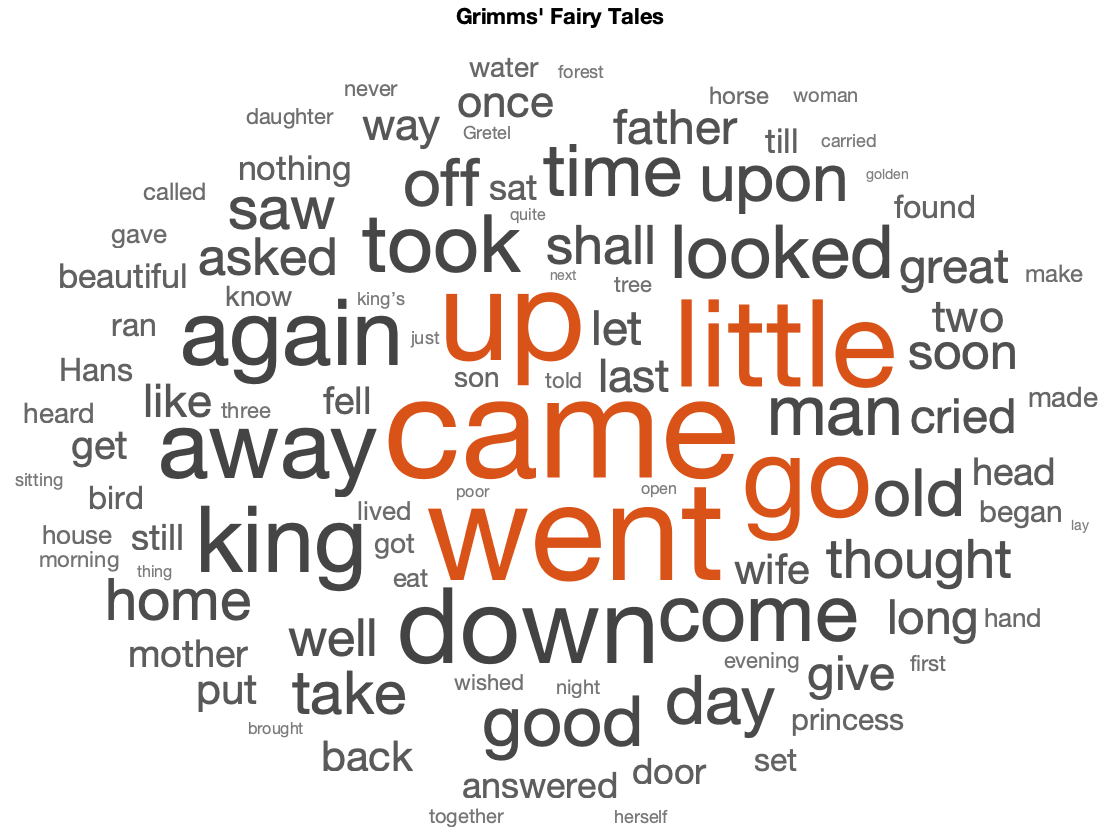

figure
wordcloud(textData);
title("Grimms' Fairy Tales")

%textData=textData(1:end-17)

documents = tokenizedDocument(textData);
ds = documentGenerationDatastore(documents);
ds = sort(ds);  

inputSize = 1;
embeddingDimension = 100;
numWords = numel(ds.Encoding.Vocabulary);
numClasses = numWords + 1;

layers = [ 
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(100)
    dropoutLayer(0.1)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

%For SGD training option
options = trainingOptions("sgdm", ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.2, ...
    LearnRateDropPeriod=5, ...
    MaxEpochs=200, ...
    Shuffle='never', ...
    MiniBatchSize=64, ...
    Plots="training-progress")

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2000
             LearnRateDropPeriod: 5
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 200
                   MiniBatchSize: 64
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'never'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
                           Plots: 'training-progress'
                  Sequence

options = trainingOptions('adam', ...
    'MaxEpochs',200, ...
    'InitialLearnRate',0.0015, ...
    'MiniBatchSize',4, ...
    'Shuffle','never', ...
    'Plots','training-progress', ...
    'Verbose',false);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:35 |        0.00% |       8.7087 |          0.0100 |
|       3 |          50 |       00:04:09 |       12.50% |       5.9772 |          0.0100 |
|       5 |         100 |       00:06:23 |       16.91% |       5.5786 |          0.0100 |
|       7 |         150 |       00:08:18 |       13.04% |       5.8462 |          0.0020 |
|      10 |         200 |       00:10:27 |       41.41% |       4.0331 |          0.0020 |
|      12 |         250 |       00:12:05 |       26.56% |       4.9820 |          0.0004 |
|      14 |         300 |       00:13:54 |       16.36% |       5.

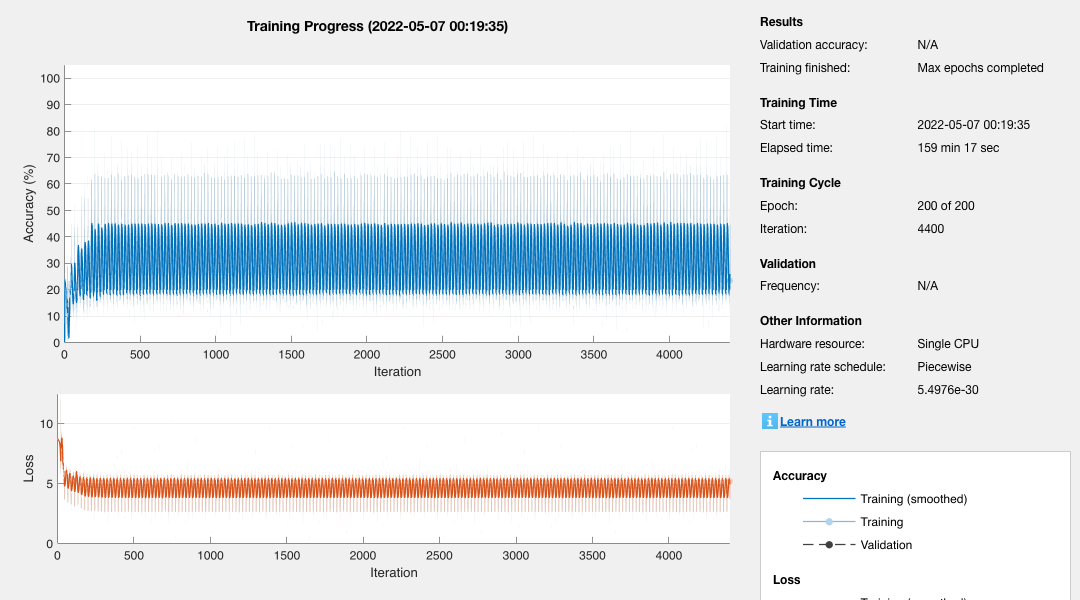

net = trainNetwork(ds,layers,options);

enc = ds.Encoding;
wordIndex = word2ind(enc,"startOfText")

wordIndex = 1

vocabulary = string(net.Layers(end).Classes);
generatedText = "";
maxLength = 500;
net = resetState(net);

while strlength(generatedText) < maxLength
    % Predict the next word scores.
    [net,wordScores] = predictAndUpdateState(net,wordIndex,'ExecutionEnvironment','cpu');
    
    % Sample the next word.
    newWord = datasample(vocabulary,1,'Weights',wordScores);
    
    % Stop predicting at the end of text.
    if newWord == "EndOfText"
        break
    end
    
    % Add the word to the generated text.
    generatedText = generatedText + " " + newWord;
    
    % Find the word index for the next input.
    wordIndex = word2ind(enc,newWord);
end
punctuationCharacters = ["." "," "’" ")" ":" "?" "!"];
generatedText = replace(generatedText," " + punctuationCharacters,punctuationCharacters);
punctuationCharacters = ["(" "‘"];
generatedText = replace(generatedText,punctuationCharacters + " ",punctuationCharacters)

generatedText = " forefinger, immutable."

net = resetState(net);
generatedText = replace(generatedText,punctuationCharacters + " ",punctuationCharacters)

generatedText = " When they had travelled’ and went away."